# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                           displayData.m               fmincg.m                    sigmoid.m                   
..                          ex4.mlx                     lib                         sigmoidGradient.m           
checkNNGradients.m          ex4_companion.mlx           nnCostFunction.m            submit.m                    
computeNumericalGradient.m  ex4data1.mat                predict.m                   token.mat                   
debugInitializeWeights.m    ex4weights.mat              randInitializeWeights.m     



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

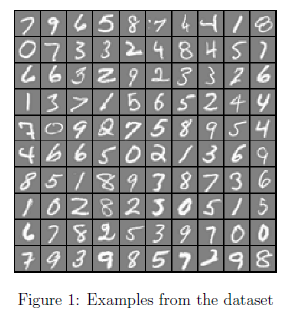

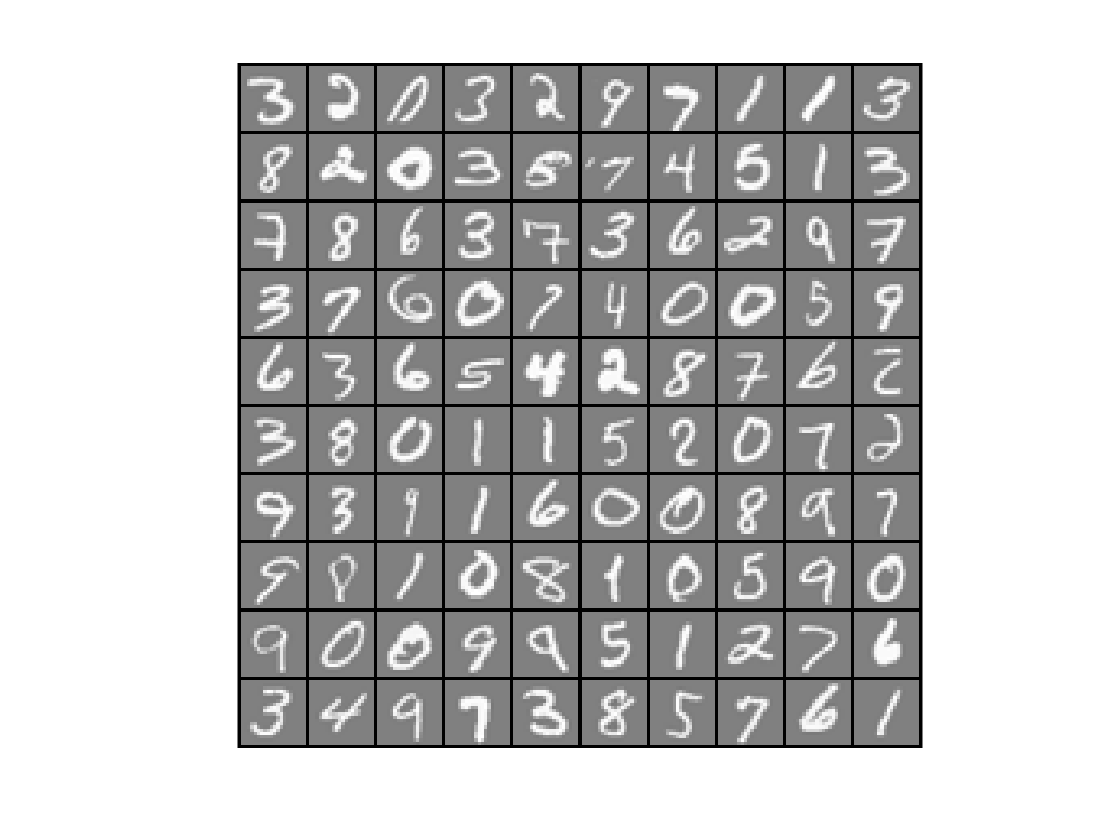

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

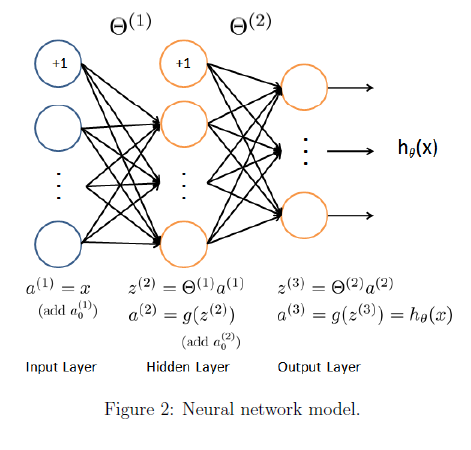

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

a2 =     1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    0.5532  

Theta2_grad =     0.0006    0.0008    0.0001    0.0015    0.0007    0.0014   -0.0002   -0.0007   -0.0012   -0.0001    0.0007   -0.0005    0.0011   -0.0006   -0.0007   -0.0009    0.0002    0.0010   -0.0005   -0.0001    0.0002    0.0005    0.0002    0.0014    0.0005    0.0009
    0.0004   -0.0003    0.0007   -0.0011    0.0005   -0.0001    0.0002   -0.0007    0.0010    0.0006    0.0013    0.0018    0.0013   -0.0010   -0.0002   -0.0011    0.0015    0.0005    0.0001    0.0012    0.0008   -0.0006   -0.0002   -0.0014    0.0014   -0.0009
    0.0004    0.0011   -0.0013    0.0018    0.0001   -0.0009   -0.0006    0.0009    0.0005    0.0004   -0.0005    0.0015   -0.0003   -0.0003   -0.0015    0.0015    0.0010   -0.0007    0.0007    0.0011    0.0011    0.0002   -0.0001    0.0007   -0.0006    0.0003
    0.0004   -0.0002   -0.0003    0.0001   -0.0011    0.0001    0.0011   -0.0003   -0.0006    0.0020   -0.0009   -0.0002    0.0006    0.0016   -0.0005    0.0003    0.0004    0.0010   -0.0001    0.0001   


fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.287629

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

a2 =     1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    0.5532  

Theta2_grad =     0.0006    0.0005    0.0001    0.0010    0.0005    0.0009   -0.0000   -0.0004   -0.0008   -0.0000    0.0005   -0.0003    0.0008   -0.0004   -0.0004   -0.0006    0.0002    0.0006   -0.0003   -0.0000    0.0001    0.0004    0.0002    0.0009    0.0004    0.0006
    0.0004   -0.0002    0.0005   -0.0007    0.0003   -0.0001    0.0001   -0.0005    0.0007    0.0004    0.0009    0.0012    0.0009   -0.0007   -0.0002   -0.0007    0.0010    0.0003    0.0000    0.0008    0.0005   -0.0004   -0.0001   -0.0009    0.0010   -0.0006
    0.0004    0.0007   -0.0009    0.0012    0.0000   -0.0006   -0.0004    0.0006    0.0003    0.0003   -0.0003    0.0010   -0.0002   -0.0002   -0.0010    0.0010    0.0007   -0.0004    0.0004    0.0008    0.0007    0.0001   -0.0001    0.0005   -0.0003    0.0002
    0.0004   -0.0002   -0.0002    0.0001   -0.0007    0.0001    0.0008   -0.0002   -0.0004    0.0013   -0.0006   -0.0001    0.0004    0.0011   -0.0004    0.0002    0.0003    0.0006   -0.0000    0.0001   

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.383770

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

ans = 0.2500

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_{l+1}$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

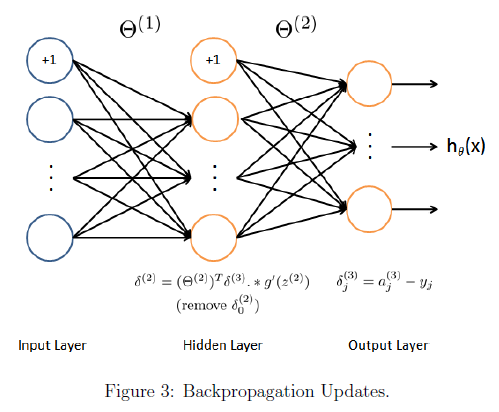

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5218    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5181    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5192    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5268    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5186    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5074    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4993    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5042    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5003    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4839    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4721
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4746
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4780


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad =     0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1584    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0504    0.0507    0.0491    0.0471    0.0465


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0507    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0507    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0507    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0507    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1110    0.0576    0.0578    0.0559    0.0537    0.0531
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0507    0.0492    0.0471    0.0466


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1641    0.1646    0.1583    0.1511    0.1496
    0.1111    0.0576    0.0578    0.0559    0.0537    0.0532
    0.0974    0.0505    0.0508    0.0492    0.0472    0.0466


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5218    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5181    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5192    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5268    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5186    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5074    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4993    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5042    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5003    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4839    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4721
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4746
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4780


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0001    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1186    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110   -0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0001    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0336    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0338    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2039    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2041    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0754    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1256    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1258    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0040    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0169    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1764    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1132   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0861    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1322
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3146    0.1187    0.2040    0.1257    0.1763    0.1324
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1110    0.0000    0.1171   -0.0041    0.1131   -0.0046
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1172   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0015


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0014


a2 = 5×6
    1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


Theta2_grad = 3×6
    0.3145    0.1187    0.2040    0.1257    0.1763    0.1323
    0.1111    0.0000    0.1171   -0.0041    0.1131   -0.0045
    0.0974    0.0337    0.0755    0.0170    0.0862    0.0016


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

a2 = 5000×26
    1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    

Theta2_grad = 10×26
    0.6287    0.0235    0.0377    0.0671    0.0971    0.0562    0.1790    0.0578    0.0764    0.1701    0.0098    0.1148    0.1479    0.1390    0.1279    0.1019    0.0606    0.0386    0.1499    0.0117   -0.0009    0.1378    0.1699    0.0367    0.0761    0.0955
    0.3646    0.0392   -0.0241    0.0056   -0.0423   -0.0850   -0.0566    0.0381    0.0233   -0.0030   -0.0172    0.0493    0.0558   -0.0088   -0.0305    0.0245    0.0588   -0.0224   -0.1092   -0.0366   -0.0218   -0.0811   -0.0068   -0.0079   -0.0314   -0.0298
    0.3960   -0.0384   -0.0486   -0.0339   -0.0601   -0.0808   -0.0226   -0.0135   -0.0149    0.0354   -0.0237   -0.0376   -0.0496    0.0247    0.0120    0.0403    0.0108    0.0331   -0.0323    0.0227   -0.0155   -0.0099    0.0103    0.0623    0.0653    0.0357
    0.4413    0.0285    0.0251    0.0196    0.0281    0.0067    0.0314    0.0180    0.0358    0.0126   -0.0019    0.0229    0.0616    0.0360    0.0334   -0.0001   -0.0072   -0.0203    0.0382   -0.0

fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.3427    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714
    0.3427    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714
    0.3427    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714
    0.3427    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.2339    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170
    0.2339    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170
    0.2339    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170
    0.2339    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1170    0.1

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.0289    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0289    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0289    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0289    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0

Iteration     1 | Cost: 3.291172e+00


a2 = 5000×26
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

Theta2_grad = 10×26
   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988
   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988
   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988
   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0

a2 = 5000×26
    1.0000    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655    0.9655
    1.0000    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740
    1.0000    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870    0.9870
    1.0000    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    0.9857    

Theta2_grad = 10×26
   -0.0831   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718
   -0.0831   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791
   -0.0831   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792
   -0.0831   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0772   -0.0

a2 = 5000×26
    1.0000    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827    0.6827
    1.0000    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970    0.6970
    1.0000    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303    0.7303
    1.0000    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    0.7257    

Theta2_grad = 10×26
   -0.0279   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141
   -0.0279   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198
   -0.0279   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199
   -0.0279   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0

a2 = 5000×26
    1.0000    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854
    1.0000    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926    0.5926
    1.0000    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102    0.6102
    1.0000    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    

Theta2_grad = 10×26
   -0.0006    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018
   -0.0006   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0006   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
   -0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Iteration     2 | Cost: 3.253283e+00


a2 = 5000×26
    1.0000    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003    0.3003
    1.0000    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171    0.3171
    1.0000    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382    0.3382
    1.0000    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    0.3074    

Theta2_grad = 10×26
   -0.0914   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533   -0.0533
    0.3837    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715    0.1715
    0.4187    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879    0.1879
    0.0269    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0

a2 = 5000×26
    1.0000    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562    0.5562
    1.0000    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648    0.5648
    1.0000    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833    0.5833
    1.0000    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    0.5776    

Theta2_grad = 10×26
   -0.0301   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162
    0.0248    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135
    0.0267    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146    0.0146
    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0

a2 = 5000×26
    1.0000    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825
    1.0000    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899    0.5899
    1.0000    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075    0.6075
    1.0000    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    0.6048    

Theta2_grad = 10×26
   -0.0041   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0017    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0019    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
   -0.0005    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

Iteration     3 | Cost: 3.253000e+00


a2 = 5000×26
    1.0000    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706    0.5706
    1.0000    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782
    1.0000    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952    0.5952
    1.0000    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    0.5916    

Theta2_grad = 10×26
   -0.0007    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0015    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0016    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0

a2 = 5000×26
    1.0000    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582    0.5582
    1.0000    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660    0.5660
    1.0000    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825    0.5825
    1.0000    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    0.5779    

Theta2_grad = 10×26
    0.0030    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026
    0.0014    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0013    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0019    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0

Iteration     4 | Cost: 3.252315e+00


a2 = 5000×26
    1.0000    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373
    1.0000    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457    0.5457
    1.0000    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611
    1.0000    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    0.5548    

Theta2_grad = 10×26
   -0.0021   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
   -0.0013   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0012   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0024   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0

a2 = 5000×26
    1.0000    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456
    1.0000    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538
    1.0000    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696    0.5696
    1.0000    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    0.5640    

Theta2_grad = 10×26
   -0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
   -0.0003   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0003   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0007   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0

Iteration     5 | Cost: 3.251913e+00


a2 = 5000×26
    1.0000    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219
    1.0000    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292    0.5292
    1.0000    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395    0.5395
    1.0000    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    

Theta2_grad = 10×26
   -0.0022   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
    0.0050    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024
    0.0053    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026
    0.0012    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0

a2 = 5000×26
    1.0000    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402    0.5402
    1.0000    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482
    1.0000    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627    0.5627
    1.0000    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    

Theta2_grad = 10×26
   -0.0007   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0009    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0010    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
   -0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Iteration     6 | Cost: 3.251819e+00


a2 = 5000×26
    1.0000    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373
    1.0000    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447    0.5447
    1.0000    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561    0.5561
    1.0000    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    0.5516    

Theta2_grad = 10×26
   -0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0010    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0010    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0

a2 = 5000×26
    1.0000    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316
    1.0000    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378    0.5378
    1.0000    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428
    1.0000    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    

Theta2_grad = 10×26
    0.0015    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0011    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0011    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0012    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0

Iteration     7 | Cost: 3.251471e+00


a2 = 5000×26
    1.0000    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299    0.5299
    1.0000    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348
    1.0000    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332    0.5332
    1.0000    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    

Theta2_grad = 10×26
   -0.0015   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
   -0.0011   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.0010   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.0016   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0

Iteration     8 | Cost: 3.251281e+00


a2 = 5000×26
    1.0000    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140
    1.0000    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119    0.5119
    1.0000    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832    0.4832
    1.0000    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    0.4928    

Theta2_grad = 10×26
   -0.0049   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015
   -0.0010   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
   -0.0034   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0

a2 = 5000×26
    1.0000    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270    0.5270
    1.0000    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306
    1.0000    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241    0.5241
    1.0000    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    0.5258    

Theta2_grad = 10×26
   -0.0023   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
   -0.0011   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
   -0.0010   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.0021   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0

Iteration     9 | Cost: 3.251231e+00


a2 = 5000×26
    1.0000    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261    0.5261
    1.0000    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296    0.5296
    1.0000    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227    0.5227
    1.0000    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    

Theta2_grad = 10×26
   -0.0018   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0015   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0

a2 = 5000×26
    1.0000    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247    0.5247
    1.0000    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278    0.5278
    1.0000    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204    0.5204
    1.0000    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    0.5224    

Theta2_grad = 10×26
   -0.0009    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0006   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0004   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0

Iteration    10 | Cost: 3.251095e+00


a2 = 5000×26
    1.0000    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293    0.5293
    1.0000    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304    0.5304
    1.0000    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271    0.5271
    1.0000    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    0.5281    

Theta2_grad = 10×26
   -0.0008    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0006   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0004   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0

Iteration    11 | Cost: 3.250961e+00


a2 = 5000×26
    1.0000    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341
    1.0000    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330
    1.0000    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348
    1.0000    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    0.5345    

Theta2_grad = 10×26
   -0.0016    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0007   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0006   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003
    0.0001    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0

a2 = 5000×26
    1.0000    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436    0.5436
    1.0000    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382    0.5382
    1.0000    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502
    1.0000    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    0.5474    

Theta2_grad = 10×26
   -0.0031    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0010   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003
    0.0009   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
   -0.0005    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0

a2 = 5000×26
    1.0000    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721    0.5721
    1.0000    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538    0.5538
    1.0000    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957
    1.0000    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    0.5854    

Theta2_grad = 10×26
   -0.0075   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0023   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
    0.0023   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0022   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0

a2 = 5000×26
    1.0000    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542
    1.0000    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998    0.5998
    1.0000    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203    0.7203
    1.0000    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    0.6921    

Theta2_grad = 10×26
   -0.0189   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021
    0.0107    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015
    0.0111    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
   -0.0051   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0

Iteration    12 | Cost: 3.245932e+00


a2 = 5000×26
    1.0000    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424    0.7424
    1.0000    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541
    1.0000    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337    0.8337
    1.0000    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    0.7971    

Theta2_grad = 10×26
   -0.0227   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
    0.0240    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068
    0.0246    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071
    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0

Iteration    13 | Cost: 3.239099e+00


a2 = 5000×26
    1.0000    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919    0.7919
    1.0000    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893    0.6893
    1.0000    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856    0.8856
    1.0000    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    0.8500    

Theta2_grad = 10×26
   -0.0229   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0316    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108
    0.0322    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110
    0.0049    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0

a2 = 5000×26
    1.0000    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162    0.8162
    1.0000    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080    0.7080
    1.0000    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079    0.9079
    1.0000    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    0.8742    

Theta2_grad = 10×26
   -0.0225    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0371    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142
    0.0377    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0082    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0

Iteration    14 | Cost: 3.232083e+00


a2 = 5000×26
    1.0000    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551    0.8551
    1.0000    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418    0.7418
    1.0000    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385    0.9385
    1.0000    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    0.9098    

Theta2_grad = 10×26
   -0.0210    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0404    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164    0.0164
    0.0410    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166    0.0166
    0.0132    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0

a2 = 5000×26
    1.0000    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934    0.8934
    1.0000    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797
    1.0000    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632    0.9632
    1.0000    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    0.9410    

Theta2_grad = 10×26
   -0.0178    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034
    0.0469    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216    0.0216
    0.0476    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217    0.0217
    0.0209    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0089    0.0

Iteration    15 | Cost: 3.218085e+00


a2 = 5000×26
    1.0000    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102    0.9102
    1.0000    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998    0.7998
    1.0000    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721    0.9721
    1.0000    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    

Theta2_grad = 10×26
   -0.0169    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035
    0.0357    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135
    0.0362    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135
    0.0201    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0073    0.0

a2 = 5000×26
    1.0000    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368    0.9368
    1.0000    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356    0.8356
    1.0000    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841    0.9841
    1.0000    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    

Theta2_grad = 10×26
   -0.0142    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039
    0.0158   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
    0.0161   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017
    0.0191    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0

Iteration    16 | Cost: 3.177850e+00


a2 = 5000×26
    1.0000    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649    0.9649
    1.0000    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946    0.8946
    1.0000    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930
    1.0000    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    0.9861    

Theta2_grad = 10×26
   -0.0374   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130   -0.0130
   -0.0004   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121   -0.0121
    0.0063   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075
   -0.0386   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0378   -0.0

a2 = 5000×26
    1.0000    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436    0.9436
    1.0000    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489    0.8489
    1.0000    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864
    1.0000    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    

Theta2_grad = 10×26
   -0.0195    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0123   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035
    0.0138   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
    0.0049   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0058   -0.0

Iteration    17 | Cost: 3.170366e+00


a2 = 5000×26
    1.0000    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501
    1.0000    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628
    1.0000    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884
    1.0000    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    0.9782    

Theta2_grad = 10×26
   -0.0232   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029
    0.0169    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0184    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0020   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0

a2 = 5000×26
    1.0000    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612    0.9612
    1.0000    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874    0.8874
    1.0000    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915
    1.0000    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    0.9837    

Theta2_grad = 10×26
   -0.0297   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085
    0.0279    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109    0.0109
    0.0294    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114
   -0.0032   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0106   -0.0

Iteration    18 | Cost: 3.137854e+00


a2 = 5000×26
    1.0000    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673    0.9673
    1.0000    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012    0.9012
    1.0000    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930
    1.0000    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    0.9864    

Theta2_grad = 10×26
   -0.0225   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054
    0.0074   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055   -0.0055
    0.0071   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067
    0.0149    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0

Iteration    19 | Cost: 3.108176e+00


a2 = 5000×26
    1.0000    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717    0.9717
    1.0000    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110    0.9110
    1.0000    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938
    1.0000    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    0.9880    

Theta2_grad = 10×26
    0.0065    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110    0.0110
    0.0130   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003
    0.0175    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025
    0.0178    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0

Iteration    20 | Cost: 3.085049e+00


a2 = 5000×26
    1.0000    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784    0.9784
    1.0000    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273    0.9273
    1.0000    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949
    1.0000    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    0.9904    

Theta2_grad = 10×26
    0.0575    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394    0.0394
    0.0240    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0294    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138    0.0138
    0.0055   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0

Iteration    21 | Cost: 3.063513e+00


a2 = 5000×26
    1.0000    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0000    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363
    1.0000    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955
    1.0000    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    0.9917    

Theta2_grad = 10×26
    0.0613    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384    0.0384
    0.0193    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069
    0.0207    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070    0.0070
   -0.0008   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0

a2 = 5000×26
    1.0000    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865    0.9865
    1.0000    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501    0.9501
    1.0000    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965
    1.0000    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    

Theta2_grad = 10×26
    0.0709    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378
    0.0116    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0064   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040
   -0.0112   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0

Iteration    22 | Cost: 3.002401e+00


a2 = 5000×26
    1.0000    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911
    1.0000    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651    0.9651
    1.0000    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    0.9955    

Theta2_grad = 10×26
    0.0225    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040
   -0.0018   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085   -0.0085
    0.0045   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039   -0.0039
   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0

Iteration    23 | Cost: 2.948080e+00


a2 = 5000×26
    1.0000    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950
    1.0000    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790    0.9790
    1.0000    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981
    1.0000    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    

Theta2_grad = 10×26
   -0.0067   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148   -0.0148
    0.0926    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816    0.0816
    0.0524    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434    0.0434
    0.0348    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0301    0.0

a2 = 5000×26
    1.0000    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921
    1.0000    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687
    1.0000    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976
    1.0000    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    0.9959    

Theta2_grad = 10×26
    0.0114   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
    0.0141    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065
    0.0133    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047
    0.0064    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0053    0.0

Iteration    24 | Cost: 2.937069e+00


a2 = 5000×26
    1.0000    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930
    1.0000    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716    0.9716
    1.0000    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976    0.9976
    1.0000    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    

Theta2_grad = 10×26
    0.0107   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048
    0.0025   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029
   -0.0000   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065   -0.0065
   -0.0015   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0

Iteration    25 | Cost: 2.927404e+00


a2 = 5000×26
    1.0000    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938    0.9938
    1.0000    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743    0.9743
    1.0000    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
    1.0000    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    

Theta2_grad = 10×26
    0.0192   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
    0.0004   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034
    0.0108    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047
   -0.0078   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0

Iteration    26 | Cost: 2.918386e+00


a2 = 5000×26
    1.0000    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945
    1.0000    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772    0.9772
    1.0000    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971
    1.0000    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    0.9962    

Theta2_grad = 10×26
    0.0266    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0063    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035
    0.0099    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051    0.0051
   -0.0062   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0

Iteration    27 | Cost: 2.903794e+00


a2 = 5000×26
    1.0000    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950    0.9950
    1.0000    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792    0.9792
    1.0000    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972
    1.0000    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    0.9965    

Theta2_grad = 10×26
    0.0182   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0032   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052
   -0.0065   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100
    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0

a2 = 5000×26
    1.0000    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948
    1.0000    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785    0.9785
    1.0000    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972    0.9972
    1.0000    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    

Theta2_grad = 10×26
    0.0211   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
    0.0000   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0010   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050
   -0.0010   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0

Iteration    28 | Cost: 2.894816e+00


a2 = 5000×26
    1.0000    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952    0.9952
    1.0000    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806    0.9806
    1.0000    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973    0.9973
    1.0000    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    

Theta2_grad = 10×26
    0.0108   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034
    0.0029    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0087    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042
    0.0056    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0

Iteration    29 | Cost: 2.886290e+00


a2 = 5000×26
    1.0000    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818    0.9818
    1.0000    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971    0.9971
    1.0000    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    0.9966    

Theta2_grad = 10×26
    0.0054   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041
    0.0032    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0029   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
    0.0026    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0

Iteration    30 | Cost: 2.873319e+00


a2 = 5000×26
    1.0000    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951    0.9951
    1.0000    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810    0.9810
    1.0000    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967    0.9967
    1.0000    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    0.9963    

Theta2_grad = 10×26
    0.0113   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015
   -0.0016   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032
    0.0026   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
   -0.0005   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0

Iteration    31 | Cost: 2.860949e+00


a2 = 5000×26
    1.0000    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946    0.9946
    1.0000    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796    0.9796
    1.0000    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960    0.9960
    1.0000    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    

Theta2_grad = 10×26
    0.0182    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014
    0.0139    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113    0.0113
    0.0070    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033
    0.0043    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0

a2 = 5000×26
    1.0000    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949
    1.0000    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804    0.9804
    1.0000    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964    0.9964
    1.0000    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    0.9961    

Theta2_grad = 10×26
    0.0145   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0054    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034
    0.0046    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0017    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0

Iteration    32 | Cost: 2.856868e+00


a2 = 5000×26
    1.0000    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945    0.9945
    1.0000    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795    0.9795
    1.0000    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958    0.9958
    1.0000    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    0.9956    

Theta2_grad = 10×26
    0.0178    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015
    0.0063    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043
    0.0046    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0045    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0

a2 = 5000×26
    1.0000    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940    0.9940
    1.0000    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781    0.9781
    1.0000    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948    0.9948
    1.0000    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    0.9949    

Theta2_grad = 10×26
    0.0224    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037
    0.0074    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057
    0.0043    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0086    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0

Iteration    33 | Cost: 2.846570e+00


a2 = 5000×26
    1.0000    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934    0.9934
    1.0000    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774    0.9774
    1.0000    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936    0.9936
    1.0000    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    0.9942    

Theta2_grad = 10×26
    0.0222    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045
    0.0002   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
    0.0026   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0061    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0

a2 = 5000×26
    1.0000    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926    0.9926
    1.0000    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762    0.9762
    1.0000    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913
    1.0000    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    0.9930    

Theta2_grad = 10×26
    0.0220    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054
   -0.0095   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093
    0.0000   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020
    0.0028    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

Iteration    34 | Cost: 2.821655e+00


a2 = 5000×26
    1.0000    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912
    1.0000    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749
    1.0000    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859
    1.0000    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    0.9905    

Theta2_grad = 10×26
    0.0154    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045    0.0045
   -0.0051   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048
    0.0004   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
   -0.0036   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0

Iteration    35 | Cost: 2.790314e+00


a2 = 5000×26
    1.0000    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915    0.9915
    1.0000    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750    0.9750
    1.0000    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883    0.9883
    1.0000    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    0.9913    

Theta2_grad = 10×26
    0.0046   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0775    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703
    0.0111    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
    0.0705    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0538    0.0

a2 = 5000×26
    1.0000    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912
    1.0000    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749
    1.0000    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862
    1.0000    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    

Theta2_grad = 10×26
    0.0142    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040
    0.0023    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0015    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0026   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0

Iteration    36 | Cost: 2.788135e+00


a2 = 5000×26
    1.0000    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911    0.9911
    1.0000    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748    0.9748
    1.0000    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863    0.9863
    1.0000    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    0.9906    

Theta2_grad = 10×26
    0.0078    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0014    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0113    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0069    0.0

Iteration    37 | Cost: 2.784423e+00


a2 = 5000×26
    1.0000    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909    0.9909
    1.0000    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744    0.9744
    1.0000    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859    0.9859
    1.0000    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    0.9903    

Theta2_grad = 10×26
    0.0052    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
   -0.0024   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
    0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
   -0.0036   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0

Iteration    38 | Cost: 2.781751e+00


a2 = 5000×26
    1.0000    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901    0.9901
    1.0000    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727    0.9727
    1.0000    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844    0.9844
    1.0000    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    0.9893    

Theta2_grad = 10×26
    0.0040    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
   -0.0004   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
    0.0007   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
   -0.0130   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0097   -0.0

Iteration    39 | Cost: 2.777795e+00


a2 = 5000×26
    1.0000    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895    0.9895
    1.0000    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713
    1.0000    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831    0.9831
    1.0000    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    

Theta2_grad = 10×26
    0.0061    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0014    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0014    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0

Iteration    40 | Cost: 2.774144e+00


a2 = 5000×26
    1.0000    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885    0.9885
    1.0000    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692    0.9692
    1.0000    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809    0.9809
    1.0000    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    0.9871    

Theta2_grad = 10×26
    0.0088    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015
   -0.0075   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
   -0.0011   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
    0.0051    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0

a2 = 5000×26
    1.0000    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891    0.9891
    1.0000    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704    0.9704
    1.0000    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822    0.9822
    1.0000    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    0.9879    

Theta2_grad = 10×26
    0.0073    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
   -0.0027   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
    0.0003   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
    0.0027    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0

Iteration    41 | Cost: 2.772894e+00


a2 = 5000×26
    1.0000    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884    0.9884
    1.0000    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689    0.9689
    1.0000    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805    0.9805
    1.0000    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    

Theta2_grad = 10×26
    0.0090    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015
   -0.0033   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
   -0.0000   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009
    0.0024    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0

a2 = 5000×26
    1.0000    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869
    1.0000    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659
    1.0000    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768    0.9768
    1.0000    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    0.9848    

Theta2_grad = 10×26
    0.0128    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026
   -0.0048   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041   -0.0041
   -0.0007   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
    0.0021    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0

a2 = 5000×26
    1.0000    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838    0.9838
    1.0000    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600    0.9600
    1.0000    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687    0.9687
    1.0000    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    0.9802    

Theta2_grad = 10×26
    0.0202    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
   -0.0073   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059
   -0.0021   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018
    0.0018    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0

Iteration    42 | Cost: 2.764696e+00


a2 = 5000×26
    1.0000    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798    0.9798
    1.0000    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533    0.9533
    1.0000    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568    0.9568
    1.0000    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    0.9740    

Theta2_grad = 10×26
    0.0224    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047
    0.0043    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052
    0.0012    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
   -0.0032    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

Iteration    43 | Cost: 2.759460e+00


a2 = 5000×26
    1.0000    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723    0.9723
    1.0000    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450    0.9450
    1.0000    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    0.9624    

Theta2_grad = 10×26
    0.0051    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0068    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079
    0.0015    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033
   -0.0132   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0050   -0.0

Iteration    44 | Cost: 2.754408e+00


a2 = 5000×26
    1.0000    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708    0.9708
    1.0000    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444    0.9444
    1.0000    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267    0.9267
    1.0000    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    0.9603    

Theta2_grad = 10×26
   -0.0030   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017
   -0.0090   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060   -0.0060
   -0.0048   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021
   -0.0098   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0

Iteration    45 | Cost: 2.749633e+00


a2 = 5000×26
    1.0000    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659    0.9659
    1.0000    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452    0.9452
    1.0000    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059    0.9059
    1.0000    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    0.9538    

Theta2_grad = 10×26
   -0.0319   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075
   -0.0096   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063   -0.0063
   -0.0067   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028
    0.0305    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0218    0.0

a2 = 5000×26
    1.0000    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698    0.9698
    1.0000    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446
    1.0000    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226    0.9226
    1.0000    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    0.9590    

Theta2_grad = 10×26
   -0.0100   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
   -0.0091   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061   -0.0061
   -0.0052   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0024    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0

Iteration    46 | Cost: 2.747871e+00


a2 = 5000×26
    1.0000    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697    0.9697
    1.0000    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446
    1.0000    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222
    1.0000    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    0.9588    

Theta2_grad = 10×26
   -0.0100   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
   -0.0059   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
   -0.0040   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
   -0.0021    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0

a2 = 5000×26
    1.0000    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696    0.9696
    1.0000    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446    0.9446
    1.0000    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214    0.9214
    1.0000    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    0.9586    

Theta2_grad = 10×26
   -0.0099   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
   -0.0004    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
   -0.0020    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
   -0.0015    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0

Iteration    47 | Cost: 2.743341e+00


a2 = 5000×26
    1.0000    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700
    1.0000    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457    0.9457
    1.0000    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219    0.9219
    1.0000    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    0.9595    

Theta2_grad = 10×26
   -0.0042   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
   -0.0016    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
   -0.0027    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
   -0.0077   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0

Iteration    48 | Cost: 2.737188e+00


a2 = 5000×26
    1.0000    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726    0.9726
    1.0000    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508    0.9508
    1.0000    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303    0.9303
    1.0000    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    0.9642    

Theta2_grad = 10×26
   -0.0081   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018
   -0.0039   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018
   -0.0022    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0011    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0

Iteration    49 | Cost: 2.734208e+00


a2 = 5000×26
    1.0000    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787    0.9787
    1.0000    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630    0.9630
    1.0000    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497    0.9497
    1.0000    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    0.9749    

Theta2_grad = 10×26
   -0.0114   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0036   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
   -0.0039   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014
    0.0336    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0208    0.0

a2 = 5000×26
    1.0000    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738
    1.0000    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534    0.9534
    1.0000    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344    0.9344
    1.0000    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    0.9665    

Theta2_grad = 10×26
   -0.0091   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
   -0.0038   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
   -0.0025    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0062    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0

Iteration    50 | Cost: 2.733326e+00


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 32.820000


## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

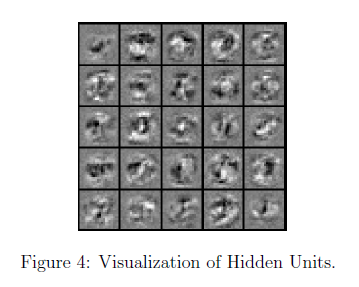

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

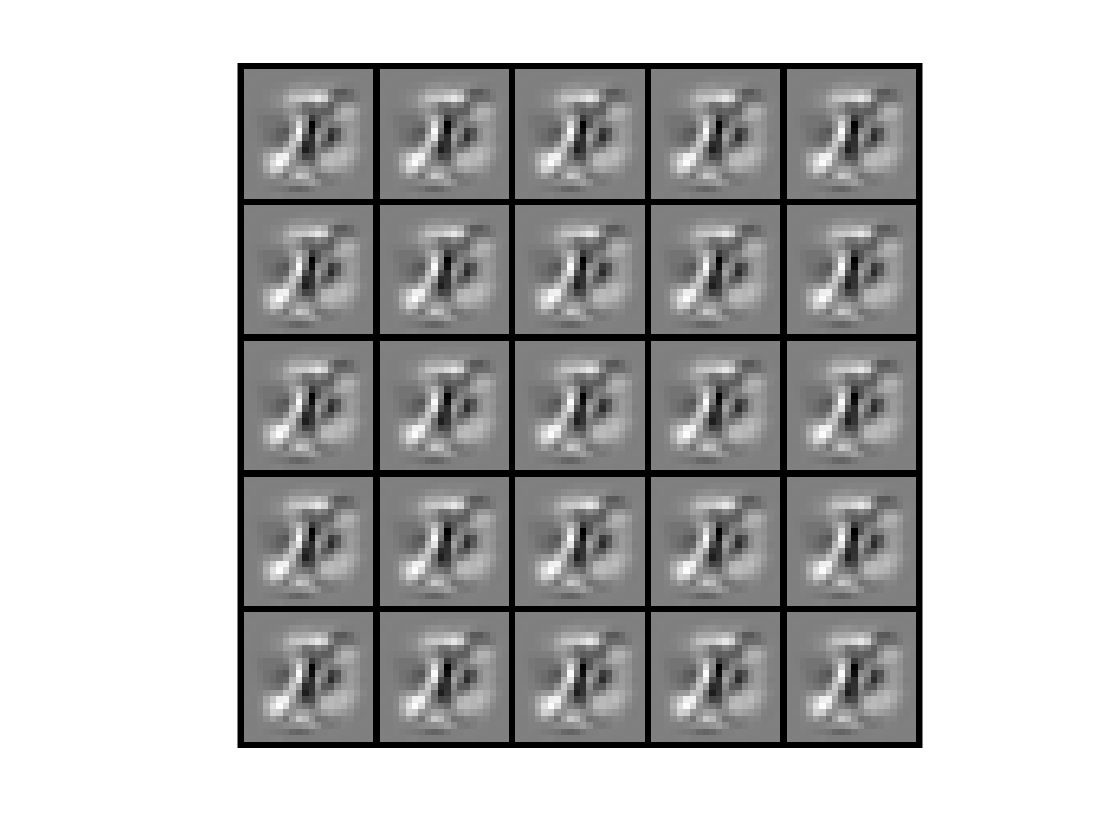

% Visualize Weights 
displayData(Theta1(:, 2:end));

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.3427    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713
    0.3427    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713
    0.3427    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713
    0.3427    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1713    0.1

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.2339    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169
    0.2339    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169
    0.2339    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169
    0.2339    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1169    0.1

a2 = 5000×26
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    

Theta2_grad = 10×26
    0.0290    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0290    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0290    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144
    0.0290    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0

Iteration     1 | Cost: 3.292204e+00


a2 = 5000×26
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

Theta2_grad = 10×26
   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988   -0.0988
   -0.0988   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989
   -0.0988   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989
   -0.0988   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0989   -0.0

a2 = 5000×26
    1.0000    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654    0.9654
    1.0000    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738    0.9738
    1.0000    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869    0.9869
    1.0000    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    0.9856    

Theta2_grad = 10×26
   -0.0830   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718   -0.0718
   -0.0830   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791   -0.0791
   -0.0830   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792   -0.0792
   -0.0830   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0771   -0.0

a2 = 5000×26
    1.0000    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826    0.6826
    1.0000    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969    0.6969
    1.0000    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302    0.7302
    1.0000    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    0.7256    

Theta2_grad = 10×26
   -0.0278   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141   -0.0141
   -0.0278   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198   -0.0198
   -0.0278   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199   -0.0199
   -0.0278   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0177   -0.0

a2 = 5000×26
    1.0000    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855    0.5855
    1.0000    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927    0.5927
    1.0000    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103    0.6103
    1.0000    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    0.6079    

Theta2_grad = 10×26
   -0.0006    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
   -0.0006   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0006   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
   -0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Iteration     2 | Cost: 3.254214e+00


a2 = 5000×26
    1.0000    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121    0.3121
    1.0000    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303    0.3303
    1.0000    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545    0.3545
    1.0000    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    0.3225    

Theta2_grad = 10×26
   -0.0922   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544   -0.0544
    0.3989    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831    0.1831
    0.4347    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002    0.2002
    0.0276    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0

a2 = 5000×26
    1.0000    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577    0.5577
    1.0000    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664    0.5664
    1.0000    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851    0.5851
    1.0000    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    0.5794    

Theta2_grad = 10×26
   -0.0300   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162   -0.0162
    0.0252    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137
    0.0272    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148
    0.0011    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0

a2 = 5000×26
    1.0000    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827    0.5827
    1.0000    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901    0.5901
    1.0000    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078    0.6078
    1.0000    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    0.6051    

Theta2_grad = 10×26
   -0.0040   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0018    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0020    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
   -0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

Iteration     3 | Cost: 3.253930e+00


a2 = 5000×26
    1.0000    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708    0.5708
    1.0000    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785    0.5785
    1.0000    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957    0.5957
    1.0000    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    0.5920    

Theta2_grad = 10×26
   -0.0005    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0016    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0016    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0

Iteration     4 | Cost: 3.253433e+00


a2 = 5000×26
    1.0000    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637    0.5637
    1.0000    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717    0.5717
    1.0000    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887    0.5887
    1.0000    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    0.5843    

Theta2_grad = 10×26
   -0.0049   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017
   -0.0009   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0007   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
   -0.0030   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0

a2 = 5000×26
    1.0000    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669
    1.0000    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747    0.5747
    1.0000    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918    0.5918
    1.0000    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    0.5877    

Theta2_grad = 10×26
   -0.0030   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0002   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
   -0.0013   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0

Iteration     5 | Cost: 3.253247e+00


a2 = 5000×26
    1.0000    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549    0.5549
    1.0000    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628
    1.0000    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782    0.5782
    1.0000    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    0.5737    

Theta2_grad = 10×26
   -0.0038   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0007   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
   -0.0018   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0

Iteration     6 | Cost: 3.252989e+00


a2 = 5000×26
    1.0000    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494    0.5494
    1.0000    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569    0.5569
    1.0000    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709    0.5709
    1.0000    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    0.5665    

Theta2_grad = 10×26
   -0.0003    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0017    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0017    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0

Iteration     7 | Cost: 3.252819e+00


a2 = 5000×26
    1.0000    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432    0.5432
    1.0000    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502    0.5502
    1.0000    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609    0.5609
    1.0000    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    0.5572    

Theta2_grad = 10×26
    0.0034    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023
   -0.0005   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007
   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008
    0.0012    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0

a2 = 5000×26
    1.0000    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469    0.5469
    1.0000    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542    0.5542
    1.0000    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669    0.5669
    1.0000    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    0.5628    

Theta2_grad = 10×26
    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0008   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0008    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0

Iteration     8 | Cost: 3.252745e+00


a2 = 5000×26
    1.0000    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460    0.5460
    1.0000    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532
    1.0000    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650    0.5650
    1.0000    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    

Theta2_grad = 10×26
   -0.3737    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543    0.3543
    0.2013   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057   -0.3057
    0.2176   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340   -0.3340
   -0.3010    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0265    0.0

Iteration     9 | Cost: 3.252642e+00


a2 = 5000×26
    1.0000    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437    0.5437
    1.0000    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505    0.5505
    1.0000    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611    0.5611
    1.0000    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    0.5576    

Theta2_grad = 10×26
   -0.0010   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0014    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0015    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
   -0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0

Iteration    10 | Cost: 3.252589e+00


a2 = 5000×26
    1.0000    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403    0.5403
    1.0000    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456    0.5456
    1.0000    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520    0.5520
    1.0000    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    0.5499    

Theta2_grad = 10×26
   -0.0033   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
    0.0024    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
    0.0027    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
   -0.0006   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

a2 = 5000×26
    1.0000    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421    0.5421
    1.0000    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481    0.5481
    1.0000    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568    0.5568
    1.0000    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    0.5539    

Theta2_grad = 10×26
   -0.0022   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.0019    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0021    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
   -0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Iteration    11 | Cost: 3.252553e+00


a2 = 5000×26
    1.0000    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422    0.5422
    1.0000    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482
    1.0000    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563    0.5563
    1.0000    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    0.5537    

Theta2_grad = 10×26
   -0.0022   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.0016    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0017    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
   -0.0005   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

a2 = 5000×26
    1.0000    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425    0.5425
    1.0000    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482
    1.0000    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555    0.5555
    1.0000    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    0.5532    

Theta2_grad = 10×26
   -0.0023   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.0009    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0011    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
   -0.0008   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0

a2 = 5000×26
    1.0000    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431    0.5431
    1.0000    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482    0.5482
    1.0000    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541    0.5541
    1.0000    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    0.5524    

Theta2_grad = 10×26
   -0.0025   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
   -0.0001   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0000   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
   -0.0014   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0

Iteration    12 | Cost: 3.252331e+00


a2 = 5000×26
    1.0000    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389    0.5389
    1.0000    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417    0.5417
    1.0000    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427
    1.0000    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    0.5428    

Theta2_grad = 10×26
    0.0017    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0005   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003
    0.0012    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0

Iteration    13 | Cost: 3.252212e+00


a2 = 5000×26
    1.0000    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269    0.5269
    1.0000    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219    0.5219
    1.0000    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085    0.5085
    1.0000    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    0.5140    

Theta2_grad = 10×26
    0.0051    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041
    0.0027    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0026    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0042    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0

a2 = 5000×26
    1.0000    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359    0.5359
    1.0000    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369    0.5369
    1.0000    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343    0.5343
    1.0000    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    

Theta2_grad = 10×26
    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023
    0.0011    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0010   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0019    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0

Iteration    14 | Cost: 3.252152e+00


a2 = 5000×26
    1.0000    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361    0.5361
    1.0000    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368
    1.0000    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341    0.5341
    1.0000    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    

Theta2_grad = 10×26
    0.0015    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0009   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0009   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0014    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0

a2 = 5000×26
    1.0000    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363    0.5363
    1.0000    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367    0.5367
    1.0000    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338    0.5338
    1.0000    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    0.5354    

Theta2_grad = 10×26
   -0.0001    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0007   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0006   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0

a2 = 5000×26
    1.0000    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366    0.5366
    1.0000    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365    0.5365
    1.0000    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333
    1.0000    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    0.5351    

Theta2_grad = 10×26
   -0.0027   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0002   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
   -0.0011   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0

Iteration    15 | Cost: 3.251819e+00


a2 = 5000×26
    1.0000    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287    0.5287
    1.0000    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246    0.5246
    1.0000    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239    0.5239
    1.0000    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    0.5245    

Theta2_grad = 10×26
   -0.0050   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.0052    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0055    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022
    0.0003    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0

a2 = 5000×26
    1.0000    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344    0.5344
    1.0000    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331    0.5331
    1.0000    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306    0.5306
    1.0000    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    0.5321    

Theta2_grad = 10×26
   -0.0034   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
    0.0016    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0018    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
   -0.0007   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

Iteration    16 | Cost: 3.251724e+00


a2 = 5000×26
    1.0000    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339    0.5339
    1.0000    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314    0.5314
    1.0000    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307    0.5307
    1.0000    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    0.5316    

Theta2_grad = 10×26
   -0.0034   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0019    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0020    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
   -0.0006   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0

a2 = 5000×26
    1.0000    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330    0.5330
    1.0000    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280    0.5280
    1.0000    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308    0.5308
    1.0000    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    0.5305    

Theta2_grad = 10×26
   -0.0033   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0023    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0024    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
   -0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0

a2 = 5000×26
    1.0000    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301    0.5301
    1.0000    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179    0.5179
    1.0000    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311    0.5311
    1.0000    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    0.5272    

Theta2_grad = 10×26
   -0.0029    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0037    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
    0.0037    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0005    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0

a2 = 5000×26
    1.0000    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214    0.5214
    1.0000    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874    0.4874
    1.0000    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320    0.5320
    1.0000    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    

Theta2_grad = 10×26
   -0.0002    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030
    0.0074    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013
    0.0070    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0038    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0

a2 = 5000×26
    1.0000    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953    0.4953
    1.0000    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973    0.3973
    1.0000    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348    0.5348
    1.0000    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    0.4883    

Theta2_grad = 10×26
    0.0275    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161
    0.0136   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0115   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010   -0.0010
    0.0199    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0102    0.0

a2 = 5000×26
    1.0000    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879    0.4879
    1.0000    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728    0.3728
    1.0000    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355
    1.0000    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    0.4801    

Theta2_grad = 10×26
    0.0426    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213    0.0213
    0.0138   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014
    0.0110   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
    0.0264    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0

Iteration    17 | Cost: 3.218489e+00


a2 = 5000×26
    1.0000    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401    0.4401
    1.0000    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030    0.2030
    1.0000    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639    0.5639
    1.0000    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    0.4286    

Theta2_grad = 10×26
    0.2756    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653    0.0653
   -0.0088   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145   -0.0145
   -0.0150   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155
    0.1060    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0237    0.0

a2 = 5000×26
    1.0000    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831    0.4831
    1.0000    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532    0.3532
    1.0000    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384    0.5384
    1.0000    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    0.4749    

Theta2_grad = 10×26
    0.0571    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255
    0.0131   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027
    0.0099   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037
    0.0317    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0137    0.0

a2 = 5000×26
    1.0000    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859    0.4859
    1.0000    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643    0.3643
    1.0000    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368    0.5368
    1.0000    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    0.4778    

Theta2_grad = 10×26
    0.0484    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230    0.0230
    0.0136   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019
    0.0106   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029
    0.0285    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.0

Iteration    18 | Cost: 3.218069e+00


a2 = 5000×26
    1.0000    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863    0.4863
    1.0000    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644    0.3644
    1.0000    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374    0.5374
    1.0000    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    0.4783    

Theta2_grad = 10×26
    0.0482    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229    0.0229
    0.0135   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020
    0.0105   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029   -0.0029
    0.0283    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0128    0.0

a2 = 5000×26
    1.0000    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870    0.4870
    1.0000    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645    0.3645
    1.0000    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387    0.5387
    1.0000    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    

Theta2_grad = 10×26
    0.0476    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227    0.0227
    0.0133   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021
    0.0104   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
    0.0279    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0126    0.0

a2 = 5000×26
    1.0000    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893    0.4893
    1.0000    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649    0.3649
    1.0000    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427    0.5427
    1.0000    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    0.4822    

Theta2_grad = 10×26
    0.0460    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220    0.0220
    0.0129   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
    0.0100   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
    0.0266    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120    0.0

a2 = 5000×26
    1.0000    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963    0.4963
    1.0000    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660    0.3660
    1.0000    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545    0.5545
    1.0000    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    0.4911    

Theta2_grad = 10×26
    0.0415    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200
    0.0116   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
    0.0088   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
    0.0229    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0103    0.0

a2 = 5000×26
    1.0000    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172    0.5172
    1.0000    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694    0.3694
    1.0000    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896    0.5896
    1.0000    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    0.5175    

Theta2_grad = 10×26
    0.0306    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150
    0.0080   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059
    0.0056   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066
    0.0129    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0

a2 = 5000×26
    1.0000    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793    0.5793
    1.0000    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796    0.3796
    1.0000    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882    0.6882
    1.0000    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    0.5956    

Theta2_grad = 10×26
    0.0173    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066
    0.0008   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113   -0.0113
   -0.0003   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111   -0.0111
   -0.0088   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0

Iteration    19 | Cost: 3.100291e+00


a2 = 5000×26
    1.0000    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993    0.6993
    1.0000    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856    0.4856
    1.0000    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907    0.7907
    1.0000    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    0.7167    

Theta2_grad = 10×26
   -0.0235   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082   -0.0082
    0.1009    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512
    0.1030    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536    0.0536
   -0.0049   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0071   -0.0

a2 = 5000×26
    1.0000    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181    0.6181
    1.0000    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116    0.4116
    1.0000    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226    0.7226
    1.0000    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    0.6351    

Theta2_grad = 10×26
    0.0010    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0221    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0216    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
   -0.0080   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0068   -0.0

Iteration    20 | Cost: 3.060597e+00


a2 = 5000×26
    1.0000    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527    0.6527
    1.0000    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509    0.4509
    1.0000    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260    0.7260
    1.0000    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    

Theta2_grad = 10×26
    0.0031    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0231    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015
    0.0203    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0193    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0

Iteration    21 | Cost: 3.035816e+00


a2 = 5000×26
    1.0000    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704    0.7704
    1.0000    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081    0.6081
    1.0000    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934    0.7934
    1.0000    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    0.7594    

Theta2_grad = 10×26
   -0.0254   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077   -0.0077
    0.0194    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0175    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0383    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0

Iteration    22 | Cost: 3.011208e+00


a2 = 5000×26
    1.0000    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161    0.8161
    1.0000    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781    0.6781
    1.0000    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250    0.8250
    1.0000    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    0.8042    

Theta2_grad = 10×26
   -0.0350   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109   -0.0109
    0.0164    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
    0.0167    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0269    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0

Iteration    23 | Cost: 2.968387e+00


a2 = 5000×26
    1.0000    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833    0.7833
    1.0000    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271    0.6271
    1.0000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900
    1.0000    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    0.7646    

Theta2_grad = 10×26
    0.0066    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030
    0.0084   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048   -0.0048
    0.0084   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052
    0.0019   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0

a2 = 5000×26
    1.0000    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976    0.7976
    1.0000    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490    0.6490
    1.0000    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053    0.8053
    1.0000    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    0.7819    

Theta2_grad = 10×26
   -0.0129   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034
    0.0116   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
    0.0118   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
    0.0112    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0

Iteration    24 | Cost: 2.951975e+00


a2 = 5000×26
    1.0000    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130
    1.0000    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773    0.6773
    1.0000    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119
    1.0000    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    0.7950    

Theta2_grad = 10×26
    0.0011    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0282    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
    0.0329    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112
   -0.0116   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0

a2 = 5000×26
    1.0000    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032    0.8032
    1.0000    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592    0.6592
    1.0000    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077    0.8077
    1.0000    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    0.7866    

Theta2_grad = 10×26
   -0.0082   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018
    0.0172    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0188    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0025   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0019   -0.0

Iteration    25 | Cost: 2.945458e+00


a2 = 5000×26
    1.0000    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057
    1.0000    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657    0.6657
    1.0000    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027    0.8027
    1.0000    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    0.7852    

Theta2_grad = 10×26
    0.0035    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021
    0.0168    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0182    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014
   -0.0002   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0027   -0.0

a2 = 5000×26
    1.0000    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106    0.8106
    1.0000    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785    0.6785
    1.0000    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924    0.7924
    1.0000    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    0.7822    

Theta2_grad = 10×26
    0.0309    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112    0.0112
    0.0158    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0168    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
   -0.0052   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0

Iteration    26 | Cost: 2.926615e+00


a2 = 5000×26
    1.0000    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401    0.8401
    1.0000    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350    0.7350
    1.0000    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040    0.8040
    1.0000    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    0.8075    

Theta2_grad = 10×26
    0.0341    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124    0.0124
    0.0102   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014
    0.0119   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017   -0.0017
   -0.0157   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0070   -0.0

Iteration    27 | Cost: 2.899634e+00


a2 = 5000×26
    1.0000    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527    0.8527
    1.0000    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585    0.7585
    1.0000    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130    0.8130
    1.0000    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    0.8209    

Theta2_grad = 10×26
   -0.0013   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
    0.0132    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0163    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
   -0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Iteration    28 | Cost: 2.876719e+00


a2 = 5000×26
    1.0000    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451    0.8451
    1.0000    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488    0.7488
    1.0000    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792    0.7792
    1.0000    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    0.7992    

Theta2_grad = 10×26
    0.0153    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050
   -0.0080   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117   -0.0117
   -0.0122   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163   -0.0163
    0.0264    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0111    0.0

a2 = 5000×26
    1.0000    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507    0.8507
    1.0000    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560    0.7560
    1.0000    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045    0.8045
    1.0000    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    0.8153    

Theta2_grad = 10×26
    0.0029    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012
    0.0072   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
    0.0080   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037
    0.0058    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0

Iteration    29 | Cost: 2.872248e+00


a2 = 5000×26
    1.0000    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558
    1.0000    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650    0.7650
    1.0000    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018    0.8018
    1.0000    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    

Theta2_grad = 10×26
    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
    0.0047   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037   -0.0037
    0.0050   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051   -0.0051
    0.0075    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0

a2 = 5000×26
    1.0000    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643    0.8643
    1.0000    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806    0.7806
    1.0000    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969    0.7969
    1.0000    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    0.8225    

Theta2_grad = 10×26
   -0.0017    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0005   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054
    0.0000   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074   -0.0074
    0.0105    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0

Iteration    30 | Cost: 2.858580e+00


a2 = 5000×26
    1.0000    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809
    1.0000    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089    0.8089
    1.0000    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099    0.8099
    1.0000    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    0.8416    

Theta2_grad = 10×26
   -0.0146   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
    0.0077    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0103    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
    0.0027   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0014   -0.0

Iteration    31 | Cost: 2.841493e+00


a2 = 5000×26
    1.0000    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866    0.8866
    1.0000    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192    0.8192
    1.0000    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119    0.8119
    1.0000    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    0.8472    

Theta2_grad = 10×26
   -0.0122   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021   -0.0021
    0.0075    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
    0.0099    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011
    0.0032   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0

Iteration    32 | Cost: 2.825845e+00


a2 = 5000×26
    1.0000    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849    0.8849
    1.0000    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183    0.8183
    1.0000    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965    0.7965
    1.0000    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    0.8393    

Theta2_grad = 10×26
    0.0144    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055
   -0.0044   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067   -0.0067
   -0.0051   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088
    0.0162    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0

a2 = 5000×26
    1.0000    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857    0.8857
    1.0000    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187    0.8187
    1.0000    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037    0.8037
    1.0000    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    0.8430    

Theta2_grad = 10×26
    0.0014    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019
    0.0010   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033
    0.0016   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044
    0.0101    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0

Iteration    33 | Cost: 2.818633e+00


a2 = 5000×26
    1.0000    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841    0.8841
    1.0000    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185    0.8185
    1.0000    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896    0.7896
    1.0000    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    0.8360    

Theta2_grad = 10×26
    0.0239    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077    0.0077
    0.0040   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005
    0.0067    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0141    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0

Iteration    34 | Cost: 2.810673e+00


a2 = 5000×26
    1.0000    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907    0.8907
    1.0000    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310    0.8310
    1.0000    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982    0.7982
    1.0000    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    0.8454    

Theta2_grad = 10×26
    0.0159    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050
    0.0093    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036
    0.0125    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046
    0.0029   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

Iteration    35 | Cost: 2.800313e+00


a2 = 5000×26
    1.0000    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944    0.8944
    1.0000    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380    0.8380
    1.0000    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057    0.8057
    1.0000    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    0.8520    

Theta2_grad = 10×26
   -0.0019   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002
   -0.0085   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092   -0.0092
   -0.0113   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127   -0.0127
   -0.0019   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0020   -0.0

Iteration    36 | Cost: 2.795638e+00


a2 = 5000×26
    1.0000    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011    0.9011
    1.0000    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508    0.8508
    1.0000    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165
    1.0000    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    0.8628    

Theta2_grad = 10×26
   -0.0303   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084   -0.0084
   -0.0085   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089
   -0.0085   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103   -0.0103
   -0.0045   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0

a2 = 5000×26
    1.0000    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968    0.8968
    1.0000    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426    0.8426
    1.0000    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095    0.8095
    1.0000    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    0.8558    

Theta2_grad = 10×26
   -0.0127   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034
   -0.0085   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
   -0.0104   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119   -0.0119
   -0.0028   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0

Iteration    37 | Cost: 2.793026e+00


a2 = 5000×26
    1.0000    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964    0.8964
    1.0000    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419    0.8419
    1.0000    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080    0.8080
    1.0000    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    0.8549    

Theta2_grad = 10×26
   -0.0102   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026   -0.0026
   -0.0009   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035   -0.0035
   -0.0002   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043   -0.0043
   -0.0008   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0

Iteration    38 | Cost: 2.789292e+00


a2 = 5000×26
    1.0000    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952    0.8952
    1.0000    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400    0.8400
    1.0000    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038    0.8038
    1.0000    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    0.8523    

Theta2_grad = 10×26
   -0.0010    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0059    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0076    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017    0.0017
    0.0040    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0

Iteration    39 | Cost: 2.786285e+00


a2 = 5000×26
    1.0000    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974    0.8974
    1.0000    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438    0.8438
    1.0000    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071    0.8071
    1.0000    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    0.8559    

Theta2_grad = 10×26
    0.0001    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
   -0.0038   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052   -0.0052
   -0.0029   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059   -0.0059
    0.0017   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0

Iteration    40 | Cost: 2.783674e+00


a2 = 5000×26
    1.0000    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006    0.9006
    1.0000    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496    0.8496
    1.0000    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121    0.8121
    1.0000    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    0.8612    

Theta2_grad = 10×26
    0.0005    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013
   -0.0010   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030   -0.0030
    0.0009   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028   -0.0028
   -0.0001   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0018   -0.0

a2 = 5000×26
    1.0000    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057    0.9057
    1.0000    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586    0.8586
    1.0000    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201    0.8201
    1.0000    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    0.8694    

Theta2_grad = 10×26
    0.0013    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0038    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009
    0.0075    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025
   -0.0029   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0

Iteration    41 | Cost: 2.777086e+00


a2 = 5000×26
    1.0000    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075    0.9075
    1.0000    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637    0.8637
    1.0000    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179    0.8179
    1.0000    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    0.8717    

Theta2_grad = 10×26
    0.0138    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058    0.0058
    0.0068    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041
    0.0082    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043
    0.0028   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0

Iteration    42 | Cost: 2.767787e+00


a2 = 5000×26
    1.0000    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069    0.9069
    1.0000    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642    0.8642
    1.0000    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156    0.8156
    1.0000    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    0.8710    

Theta2_grad = 10×26
    0.0113    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048    0.0048
   -0.0064   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054   -0.0054
   -0.0067   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066   -0.0066
    0.0067    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0

Iteration    43 | Cost: 2.759357e+00


a2 = 5000×26
    1.0000    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107
    1.0000    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718    0.8718
    1.0000    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253
    1.0000    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    0.8784    

Theta2_grad = 10×26
   -0.0053   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0053    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029
    0.0087    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049
    0.0028   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0

Iteration    44 | Cost: 2.752411e+00


a2 = 5000×26
    1.0000    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105    0.9105
    1.0000    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757    0.8757
    1.0000    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254    0.8254
    1.0000    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    0.8799    

Theta2_grad = 10×26
   -0.0190   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046   -0.0046
   -0.0032   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034   -0.0034
   -0.0125   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108   -0.0108
    0.0025    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0

a2 = 5000×26
    1.0000    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107    0.9107
    1.0000    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728    0.8728
    1.0000    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253    0.8253
    1.0000    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    0.8788    

Theta2_grad = 10×26
   -0.0091   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.0030    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013
    0.0029    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006
    0.0028   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

Iteration    45 | Cost: 2.750729e+00


a2 = 5000×26
    1.0000    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112    0.9112
    1.0000    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748    0.8748
    1.0000    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260    0.8260
    1.0000    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    0.8800    

Theta2_grad = 10×26
   -0.0097   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038   -0.0038
   -0.0050   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053   -0.0053
    0.0024    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0

Iteration    46 | Cost: 2.748544e+00


a2 = 5000×26
    1.0000    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117    0.9117
    1.0000    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764    0.8764
    1.0000    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264    0.8264
    1.0000    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    0.8810    

Theta2_grad = 10×26
   -0.0081   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
   -0.0007   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015   -0.0015
    0.0003   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011   -0.0011
    0.0020    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

a2 = 5000×26
    1.0000    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128    0.9128
    1.0000    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794    0.8794
    1.0000    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272    0.8272
    1.0000    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    0.8830    

Theta2_grad = 10×26
   -0.0047   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004
    0.0057    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035
    0.0117    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0013   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0

Iteration    47 | Cost: 2.742364e+00


a2 = 5000×26
    1.0000    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115    0.9115
    1.0000    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802    0.8802
    1.0000    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207    0.8207
    1.0000    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    0.8811    

Theta2_grad = 10×26
    0.0089    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030
    0.0030    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0006    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004
    0.0024    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0

Iteration    48 | Cost: 2.737054e+00


a2 = 5000×26
    1.0000    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157    0.9157
    1.0000    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903    0.8903
    1.0000    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258    0.8258
    1.0000    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    0.8887    

Theta2_grad = 10×26
    0.0142    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043
   -0.0063   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044   -0.0044
   -0.0132   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093   -0.0093
   -0.0024   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0

Iteration    49 | Cost: 2.732743e+00


a2 = 5000×26
    1.0000    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222    0.9222
    1.0000    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036    0.9036
    1.0000    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363
    1.0000    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    0.9002    

Theta2_grad = 10×26
    0.0112    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036
   -0.0031   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0012    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008
   -0.0072   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0033   -0.0

Iteration    50 | Cost: 2.726444e+00



% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 32.160000


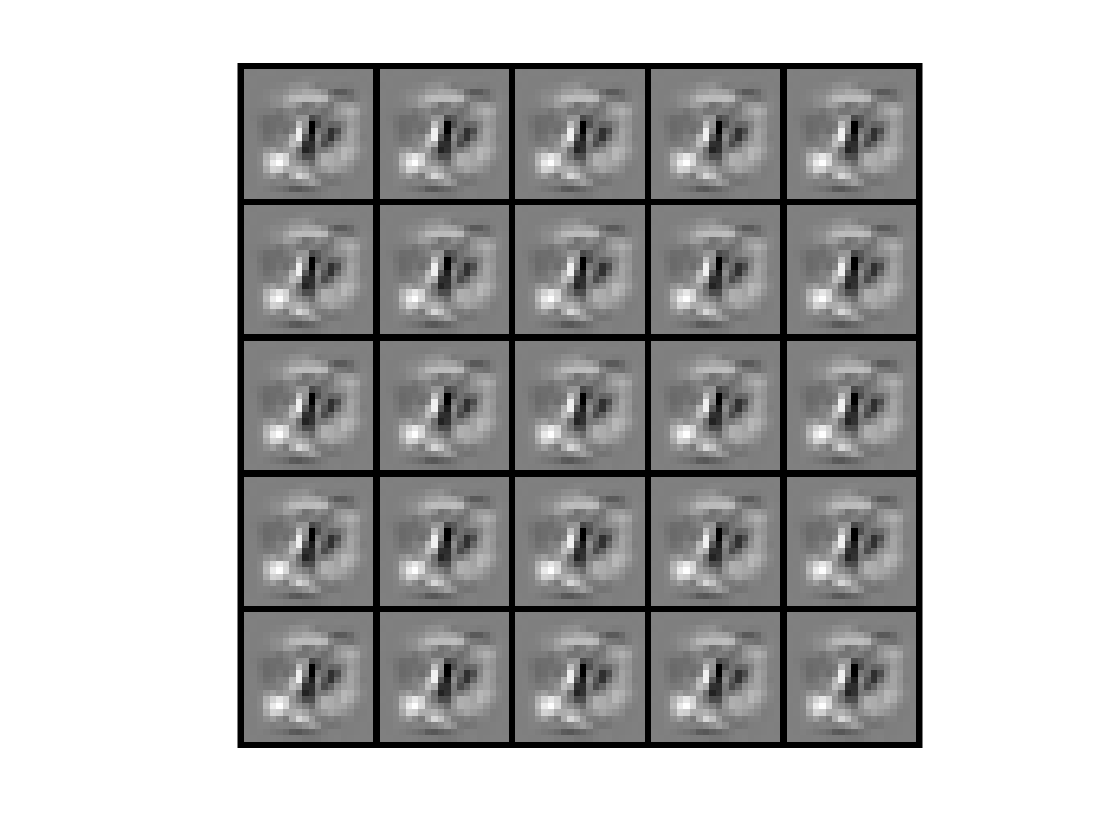


% Visualize Weights 
displayData(Theta1(:, 2:end));

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

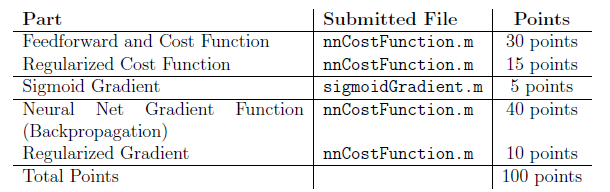

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.